clc
clear

[Y , Fs] = audioread('testaudio.ogg'); % Input Audio Signal to Matlab


Filtered_Audio = filter(LowPass, Y)

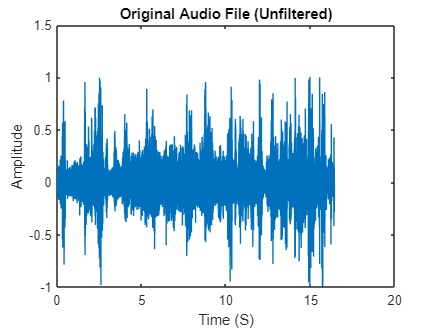


sound(Filtered_Audio,Fs)


% To filter again...
% Find FFT of Filtered_Audio
% out = filter( FUNCTION FILTER, Filtered_Audio)
% type filterdesigner in command window



[N , P] = size(Y); % Determines how many samples audio file has

sampling_period = 1 / Fs ; % Sampling Period

t_max = (N-1)*sampling_period;

t = 0:sampling_period:t_max;

plot(t , Y) % Plot Original Audio File
xlabel('Time (S)');
ylabel('Amplitude');
title('Original Audio File (Unfiltered)')

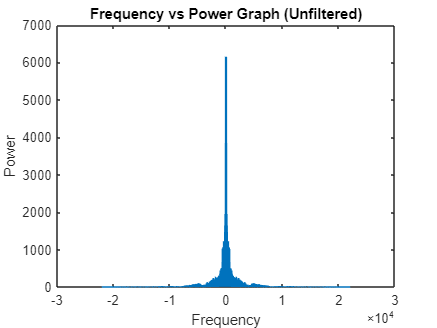





f = -Fs/2:Fs/(N-1):Fs/2; % Used for plotting frequency Spectrum

fft_Y = fftshift(fft(Y)); % Applies Fourier Transform to Audio File

plot(f,abs(fft_Y));
xlabel('Frequency');
ylabel('Power');
title('Frequency vs Power Graph (Unfiltered)')

function Hd = LowPass4K
%LOWPASS4K Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.12 and Signal Processing Toolbox 9.0.
% Generated on: 02-May-2022 22:09:02

% Equiripple FIR Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fpass = 9600;            % Passband Frequency
Fstop = 12000;           % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.0001;          % Stopband Attenuation
dens  = 16;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);
end
% [EOF]


function Hd = BandPass
%BANDPASS Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.12 and Signal Processing Toolbox 9.0.
% Generated on: 02-May-2022 22:17:45

% Butterworth Bandpass filter designed using FDESIGN.BANDPASS.

% All frequency values are in Hz.
Fs = 44100;  % Sampling Frequency

N   = 5000;    % Order
Fc1 = 1500;   % First Cutoff Frequency
Fc2 = 3000;  % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
Hd = design(h, 'butter');
end


function Hd = LowPass
%LOWPASS Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.12 and Signal Processing Toolbox 9.0.
% Generated on: 02-May-2022 22:26:00

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 44100;  % Sampling Frequency

N     = 100;    % Order
Fpass = 250;   % Passband Frequency
Fstop = 500;  % Stopband Frequency
Wpass = 1;      % Passband Weight
Wstop = 1;      % Stopband Weight
dens  = 20;     % Density Factor

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, [0 Fpass Fstop Fs/2]/(Fs/2), [1 1 0 0], [Wpass Wstop], ...
           {dens});
Hd = dfilt.dffir(b);
end

% [EOF]
